% initial data
Psi_nom = 0.227;
R_a = 0.32;
L_a = 0.0058;
U_nom = 48;
M_nom = 2.6;
J = 0.0145413;

K = 1;

T_delta = 0.1;
K_p = 0.6*K;
K_i = (2*K_p)/0.1;
K_d = K_p*T_delta/8;

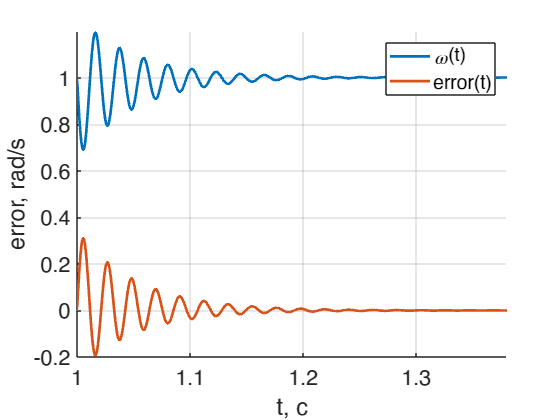

t = out.tout;

figure;
hold on

omega = squeeze(out.yout{2}.Values.Data);
plot(t, omega, LineWidth=2)
grid on
ylabel('\omega, rad/s', 'FontSize', 14)

error = squeeze(out.yout{3}.Values.Data);
plot(t, error, LineWidth=2)
ylabel('error, rad/s', 'FontSize', 14)
xlim([1 1.38])
legend('\omega(t)', 'error(t)')
grid on
xlabel('t, с', 'FontSize', 16)

ax = gca;
ax.FontSize = 16; 
hold off

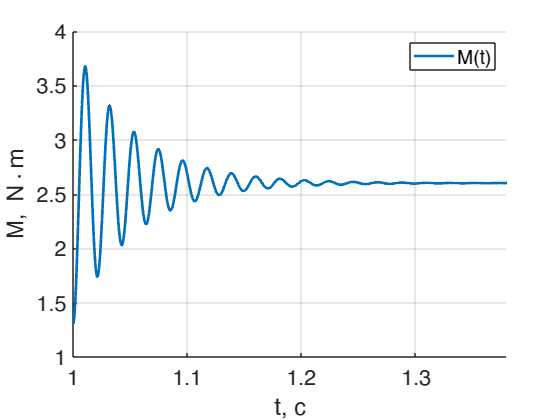

t = out.tout;

figure;
hold on

m = squeeze(out.yout{1}.Values.Data);
plot(t, m, LineWidth=2)
ylabel('M, N\cdotm', 'FontSize', 14)
legend('M(t)')
grid on
xlabel('t, с', 'FontSize', 16)
ax = gca;
ax.FontSize = 16; 
hold off
xlim([1 1.38])